# Sistema masa resorte amortiguador

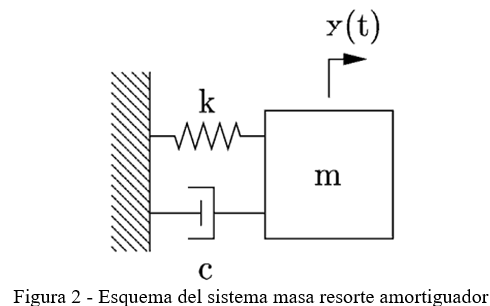


$$m\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }x+c\frac{\textrm{d}}{\textrm{d}t}x+\mathrm{kx}=0$$



$$\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }x=-\frac{c}{m}\left(\frac{\textrm{d}}{\textrm{d}t}x\right)-\frac{k}{m}x$$



$$y=\left\lbrack \begin{array}{c}
x\\
v
\end{array}\right\rbrack$$


y'=M*y

y0=[1;0];
tf = 15;
h = 0.1;
m = 20;     %kg
k = 20;     %N/m

## Sistema sin amortiguamiento

Amortiguamiento va a estar oscilando

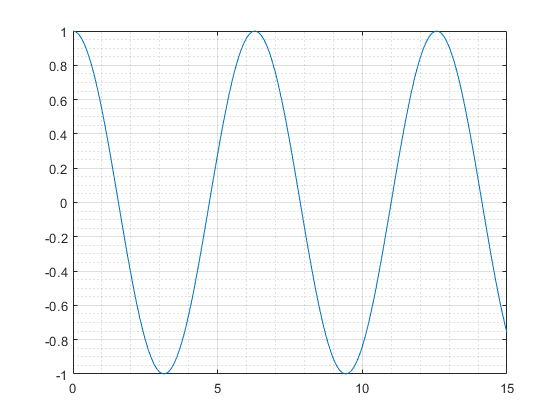

c = 0;
M = [0 1;(-k/m) (-c/m)];
f = @(t,y) M*y;
[t,y] = ivps(f,0,tf,y0,h,4);
plot (t,y(1,:));
grid on;
grid minor;

lambda = eig(M);
T = 2*pi*imag(lambda(1));

## Sistema sub-amortiguado


$$c^2 -4\mathrm{mk}<0$$


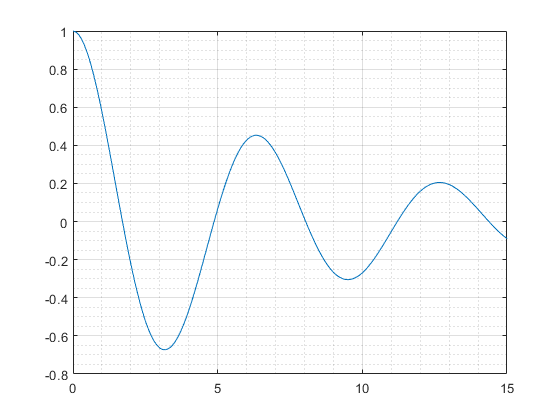

c = 5;
M = [0 1;(-k/m) (-c/m)];
f = @(t,y) M*y;
[t,y] = ivps(f,0,tf,y0,h,4);
plot (t,y(1,:));
grid on;
grid minor;

lambda = eig(M);

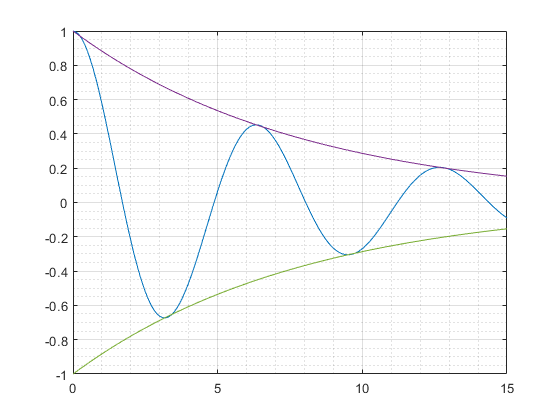

p = real(lambda(1));
hold on;
plot(t,(y0(1)*exp(p*t)));
plot(t,(-y0(1)*exp(p*t)));